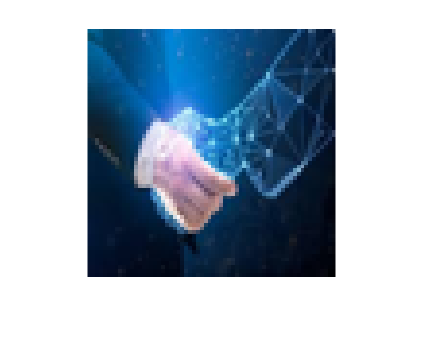

clear all;
close all;

fr_b = 8;

hand = imread("hand.jpg");
hand64 = imresize(hand,[64 64]);
figure
imshow(hand64, 'InitialMagnification', 400)


hand64_YCC = RGB2YCbCr_fix_img(hand64);

Unable to perform assignment because the size of the left side is 1-by-1-by-3 and the size of the right side is 3-by-3.

Error in segmantation_fixed>RGB2YCbCr_fix_img (line 58)
        out_img(i, j, :) = RGB2YCbCr_fix(in_img(i, j, :));

figure
subplot(3, 1, 1)
imshow(hand64_YCC(:, :, 1), 'InitialMagnification', 400)
subplot(3, 1, 2)
imshow(hand64_YCC(:, :, 2), 'InitialMagnification', 400)
subplot(3, 1, 3)
imshow(hand64_YCC(:, :, 3), 'InitialMagnification', 400)
figure
imshow(hand64_YCC, 'InitialMagnification', 400)

%colorThresholder(hand64_YCC);

hand_BW = bin_img(hand64_YCC);
figure
imshow(hand_BW, 'InitialMagnification', 400)

hand64_mask_filt = medfilt2(hand_BW,[4 4]);
hand64_mask_filt = medfilt2(hand64_mask_filt,[4 4]);
figure
imshow(hand64_mask_filt, 'InitialMagnification', 400)

props = regionprops(hand64_mask_filt);
xCOM = props.Centroid(1)
yCOM = props.Centroid(2)

hand64_out = 255 * repmat(uint8(hand64_mask_filt), 1, 1, 3);
hand64_out = insertShape(hand64_out, 'line', [xCOM 0 xCOM 63], 'Color','red');
hand64_out = insertShape(hand64_out, 'line', [0 yCOM 63 yCOM], 'Color','red');

figure, imshow(hand64_out, 'InitialMagnification', 400);
%hold on;
%rectangle('Position', props.BoundingBox, 'EdgeColor', 'g')

imwrite(hand64_out,"hand64_out.ppm")

function [output] = RGB2YCbCr_fix(input)
    fr_b = 8;
    A = [fi(0.299, 1, 18, fr_b),        fi(0.587, 1, fr_b),     fi(0.114, 1, 18, fr_b);
            fi(-0.168736, 1, 18, fr_b), fi(-0.331264, 1, fr_b), fi(0.5, 1, 18, fr_b);  
            fi(0.5, 1, 18, fr_b),       fi(-0.418688, 1, fr_b), fi(-0.081312, 1, 18, fr_b)];

    B = [fi(0, 1, 18, fr_b); fi(128, 1, 18, fr_b); fi(128, 1, 18, fr_b)];
    input = fi(input(:,:)', 1, 18, fr_b);
    output = A.*input + B;
end %RGB2YCbCr


function [out_img] = RGB2YCbCr_fix_img(in_img)
out_img = zeros(size(in_img));
for i = 1:64
    for j = 1:64
        out_img(i, j, :) = RGB2YCbCr_fix(in_img(i, j, :));
    end %for
end %for
out_img = cast(out_img, 'uint8');
end

function [output] = binarization(input)
    if ((110 < input(1)) && (input(1) < 256) ... Y
            && (-1 < input(2)) && (input(2) < 150) ... Cb
            && (-1 < input(1)) && (input(1) < 256)) %Cr
        output = true;
    else
        output = false;
    end %if
end %function

function [out_img] = bin_img(in_img)
out_img = zeros(size(in_img(:, :, 1)));
for i = 1:64
    for j = 1:64
        out_img(i, j) = binarization(in_img(i, j, :));
    end %for
end %for
end